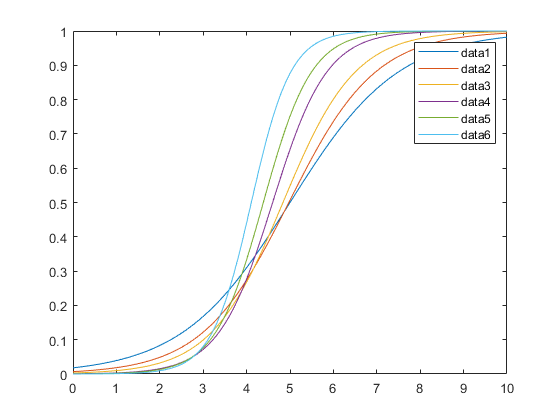

% Смгмоид

x= linspace(0,10,101);
fx1 = 1./(1+exp(-0.8*(x-5)));
fx2 = 1./(1+1.25*exp(-1.0*(x-4.75)));
fx3 = 1./(1+1.5*exp(-1.2*(x-4.5)));
fx4 = 1./(1+1.75*exp(-1.6*(x-4.25)));
fx5 = 1./(1+2*exp(-1.8*(x-4.0)));
fx6 = 1./(1+2.2*exp(-2.2*(x-3.75)));
plot(x,fx1, x,fx2,x,fx3,x,fx4,x,fx5,x,fx6)
legend()

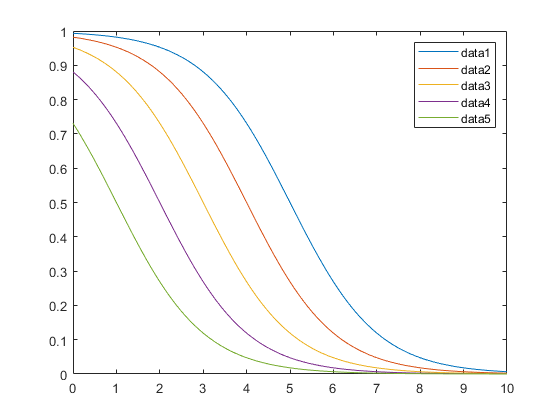

fxs1(1, :)=1-1./(1+exp(-1*(x-5)));
fxs1(2, :)=1-1./(1+exp(-1*(x-4)));
fxs1(3, :)=1-1./(1+exp(-1*(x-3)));
fxs1(4, :)=1-1./(1+exp(-1*(x-2)));
fxs1(5, :)=1-1./(1+exp(-1*(x-1)));
plot(x,fxs1)
legend()

% mSigmod = zeros(6, 101);
d = zeros(6, 101);
ts=0:100;
sd = 6; 
sdsn = 0.25

sdsn = 0.2500

betta = 0.6

betta = 0.6000

sm_bet = 0.3

sm_bet = 0.3000

alfa = 1.0 

alfa = 1

sm_alfa = 0.3

sm_alfa = 0.3000

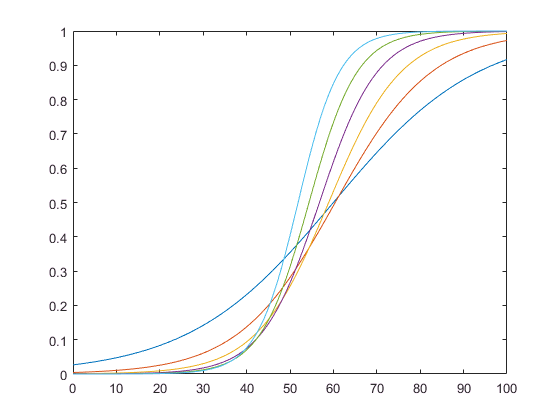

fSigm = @(k) 1. / (1 + ((alfa+k* sm_alfa) * exp(-(betta +k*sm_bet) * (ts/10  - (sd-k*sdsn)))));

for i=1:6
    d(i, :)= fSigm(i-1);       
end

plot(ts, d(1, :), ts, d(2, :), ts, d(3, :), ts, d(4, :), ts, d(5, :), ts, d(6, :))

%d = mSigmod;
[i0, j0] =size(d)

i0 = 6

j0 = 101

for k=i0-1:-1:1
    disp(k)
    count = length(d(k,d(k,:) > d(k+1, :)))
    d(k,1:count) = d(k+1,1:count);
    
end

     5



count = 37

     4



count = 43

     3



count = 49

     2



count = 55

     1



count = 62

%       for i in range(len( self.d)-2, -1, -1):
%             print(f" ----> {i}  ")
%             _count = len(self.d[i+1][0][self.d[i][0] > self.d[i+1][0]])
%             self.d[i][0][:_count] = self.d[i+1][0][:_count]
%             self.d[i] = (copy.deepcopy(self.d[i][0]), self.d[i][1])
% 
%         self.sig = {}
%         for key, value in self.d.items():
%             print(f" ----> формируем sig   {key}  ")
%             self.sig[key] = value[0]

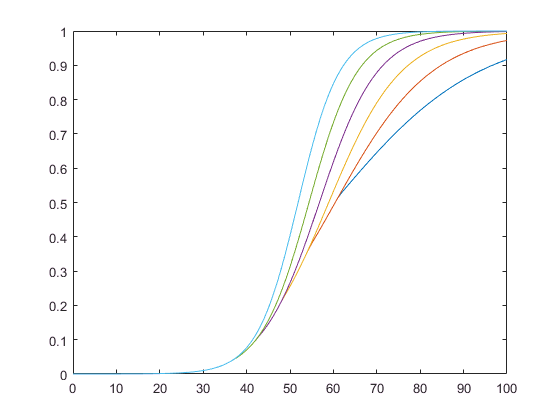

plot(ts, d(1, :), ts, d(2, :), ts, d(3, :), ts, d(4, :), ts, d(5, :), ts, d(6, :))